% Load the combined data for a specific condition (e.g., Both Eyes Closed)
load('combinedEEGData_cond1.mat'); % This loads combinedData_cond1

combinedData_cond = combinedData_cond1;

% Extract features, labels, electrodes, and subject IDs
alphaPower = combinedData_cond(:, 1);
betaPower = combinedData_cond(:, 2);
labels = combinedData_cond(:, 3); % 0 for Control, 1 for Amblyopia
electrodes = combinedData_cond(:, 4); % Electrode numbers (1: O1, 2: Oz, 3: O2)
subjectIDs = combinedData_cond(:, 5); % Subject IDs

% Create the feature matrix and labels
X = [alphaPower, betaPower];
y = labels;

% Get unique subject IDs
uniqueSubjects = unique(subjectIDs);

% Initialize variables to store accuracies
accuracies = zeros(length(uniqueSubjects), 1);

% Perform Leave-One-Subject-Out Cross-Validation
for i = 1:length(uniqueSubjects)
    % Get the test indices for the current subject
    testIdx = (subjectIDs == uniqueSubjects(i));
    % Training indices are all other subjects
    trainIdx = ~testIdx;
    
    % Training data
    X_train = X(trainIdx, :);
    y_train = y(trainIdx);
    
    % Test data
    X_test = X(testIdx, :);
    y_test = y(testIdx);
    
    % Train the SVM classifier
    SVMModel = fitcsvm(X_train, y_train);
    
    % Predict on test data
    y_pred = predict(SVMModel, X_test);
    
    % Compute accuracy for this subject
    accuracies(i) = sum(y_pred == y_test) / length(y_test);
end

% Compute overall accuracy
overallAccuracy = mean(accuracies) * 100;

% Display results
fprintf('Leave-One-Subject-Out Cross-Validation Results:\n');

Leave-One-Subject-Out Cross-Validation Results:


for i = 1:length(uniqueSubjects)
    fprintf('Subject %d Accuracy: %.2f%%\n', uniqueSubjects(i), accuracies(i) * 100);
end

Subject 1 Accuracy: 100.00%
Subject 2 Accuracy: 16.67%
Subject 3 Accuracy: 100.00%
Subject 4 Accuracy: 87.50%
Subject 5 Accuracy: 0.00%
Subject 6 Accuracy: 37.50%
Subject 7 Accuracy: 100.00%
Subject 8 Accuracy: 25.00%
Subject 9 Accuracy: 87.50%
Subject 10 Accuracy: 95.83%
Subject 11 Accuracy: 12.50%
Subject 12 Accuracy: 37.50%
Subject 13 Accuracy: 12.50%


fprintf('Overall SVM Accuracy: %.2f%%\n', overallAccuracy);

Overall SVM Accuracy: 54.81%


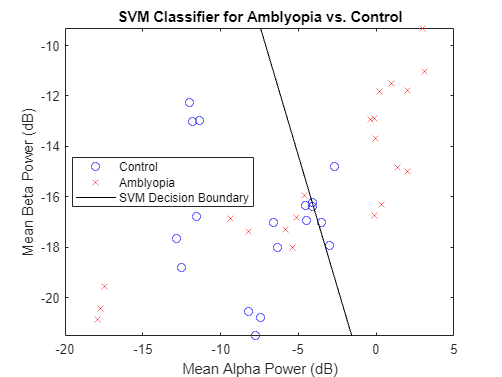

% Train SVM on full dataset
SVMModel = fitcsvm(X, y);

% Plot the data
figure;
gscatter(X(:,1), X(:,2), y, 'br', 'ox');
hold on;

% Plot SVM decision boundary
% Create a grid of points
d = 0.1;
[x1Grid, x2Grid] = meshgrid(min(X(:,1)):d:max(X(:,1)), min(X(:,2)):d:max(X(:,2)));
xGrid = [x1Grid(:), x2Grid(:)];
[~, scores] = predict(SVMModel, xGrid);

% Plot the decision boundary
contour(x1Grid, x2Grid, reshape(scores(:,2), size(x1Grid)), [0 0], 'k');

xlabel('Mean Alpha Power (dB)');
ylabel('Mean Beta Power (dB)');
legend('Control', 'Amblyopia', 'SVM Decision Boundary');
title('SVM Classifier for Amblyopia vs. Control');
hold off;